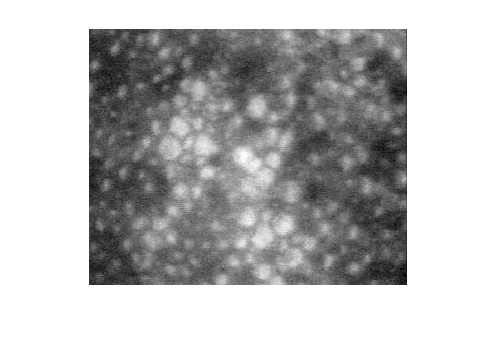

orig = imread('cornea.tif');
figure, imshow(orig);

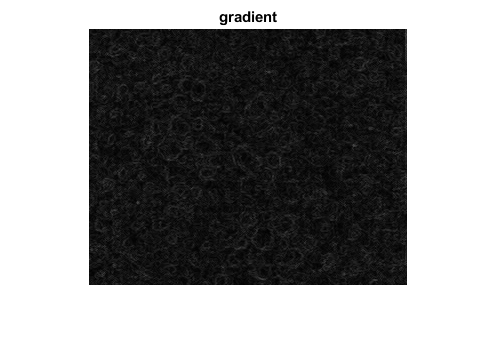

ee = strel('disk',1); 
% calculem el gradient. Ho podem fer morfològic
grad=imsubtract(imdilate(orig,ee),imerode(orig,ee));
figure,imshow(grad),title('gradient')

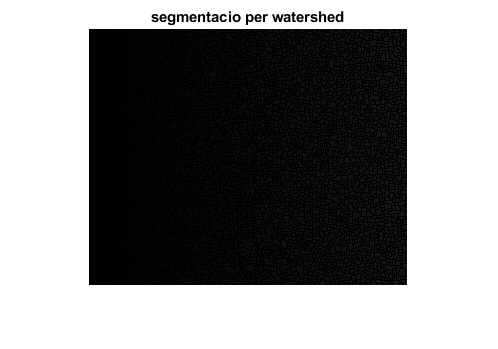

% mirem de segmentar les cèlules fent watershed sobre la imatge gradient
segm=watershed(grad);
figure,imshow(segm), title('segmentacio per watershed')

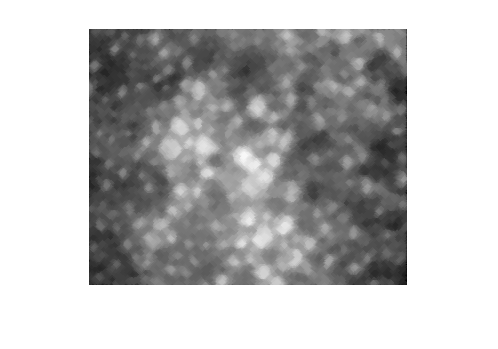

% resultat sobresegmentat. Cal treballar amb markers
%% marker-controlled watershed
% usarem els màxims regionals com a markers de les cèlules
% la imatge és molt sorollosa. Cal filtrar abans
ee=strel('disk',2);
filt=imopen(imclose(orig,ee),ee); %filtre OC
figure,imshow(filt)

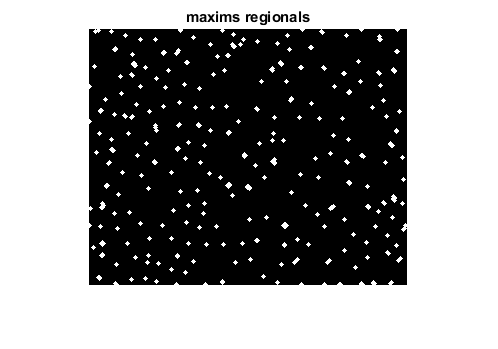

rm=imregionalmax(filt);
figure,imshow(rm),title('maxims regionals')

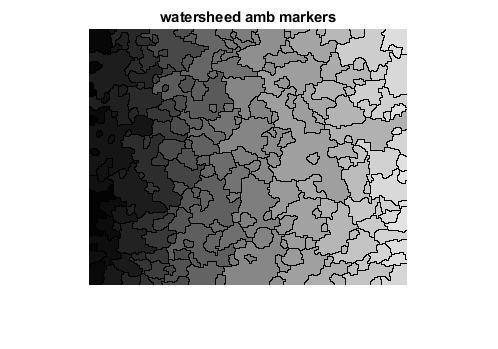

% Usem els maxims regionals com a markers pel watershed
segm=watershed(imimposemin(grad,rm));
figure,imshow(segm),title('watersheed amb markers')

Feu un overlay, en color, dels contorns obtinguts sobre la imatge original. Us sembla correcta la segmentació? O ens em oblidat alguna cosa ?

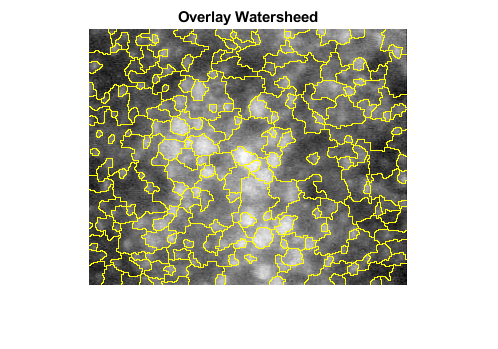

origR = orig;
origG = orig;
origB = orig;
origR(segm==0) = 255;
origG(segm==0) = 255;
origB(segm==0) = 0;
origRGB = cat(3,origR,origG,origB);
imshow(origRGB),title('Overlay Watersheed')

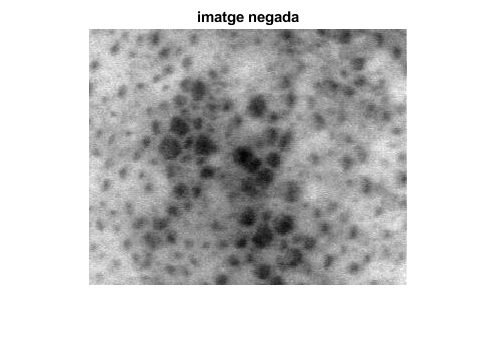

%% Cal trobar un marker pel fons
% L'obtenim fent el watershed de la imatge negada.
%Usem com a markers els mateixos maxims d'abans
Norig=imcomplement(orig);
figure,imshow(Norig),title('imatge negada')

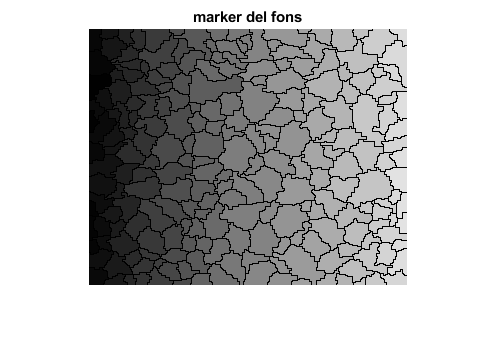

fons=watershed(imimposemin(Norig,rm));
figure,imshow(fons),title('marker del fons')

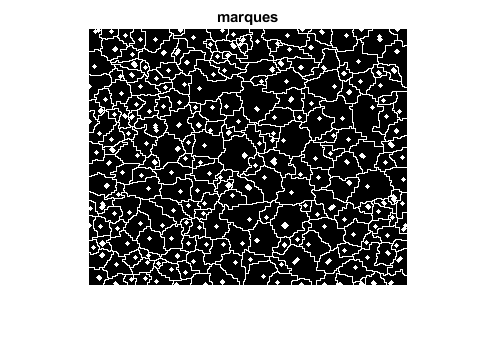

% Fem una imatge de markers a partir de les celules i del fons
markers=~fons|rm;
figure,imshow(markers),title('marques')

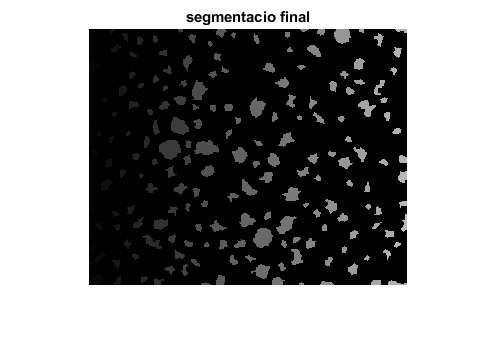

% fem el watershed amb les noves marques
segm=watershed(imimposemin(grad,markers));
figure,imshow(segm),title('segmentacio final')

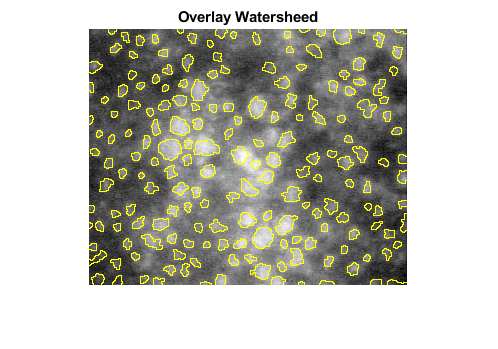


origR = orig;
origG = orig;
origB = orig;
origR(segm==0) = 255;
origG(segm==0) = 255;
origB(segm==0) = 0;
origRGB = cat(3,origR,origG,origB);
imshow(origRGB),title('Overlay Watersheed')

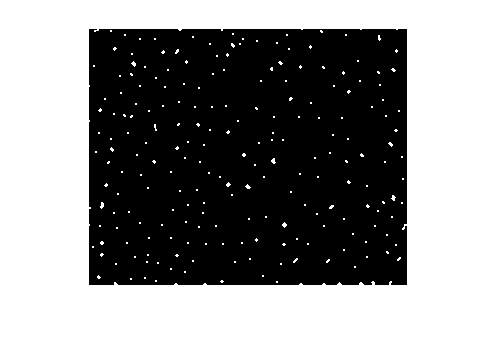


ee = strel('square',2);
rmAux = imerode(rm, ee);
imshow(rmAux)

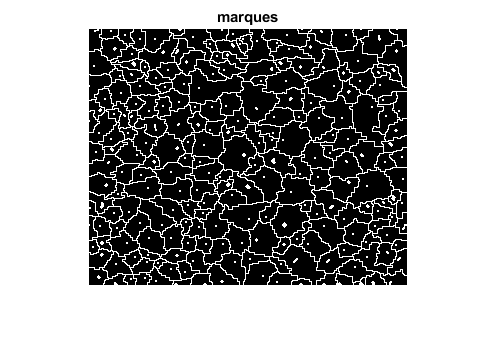

markers=~fons|rmAux;
figure,imshow(markers),title('marques')

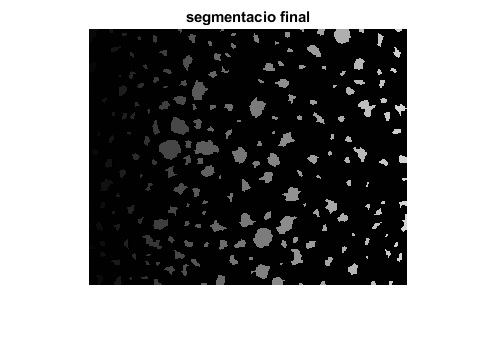


% fem el watershed amb les noves marques
segm=watershed(imimposemin(grad,markers));
figure,imshow(segm),title('segmentacio final')

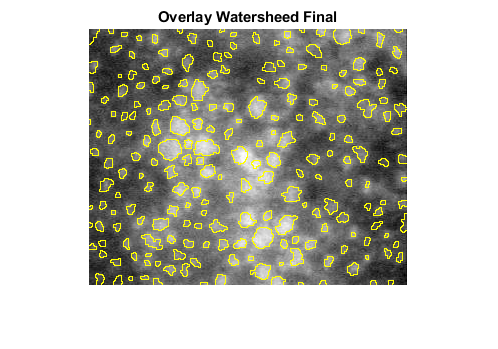


origR = orig;
origG = orig;
origB = orig;
origR(segm==0) = 255;
origG(segm==0) = 255;
origB(segm==0) = 0;
origRGB = cat(3,origR,origG,origB);
imshow(origRGB),title('Overlay Watersheed Final')

clear all
im  = imread('pepper.png');
[MAXFILA MAXCOL chan]=size(im)

MAXFILA = 512

MAXCOL = 512

chan = 3

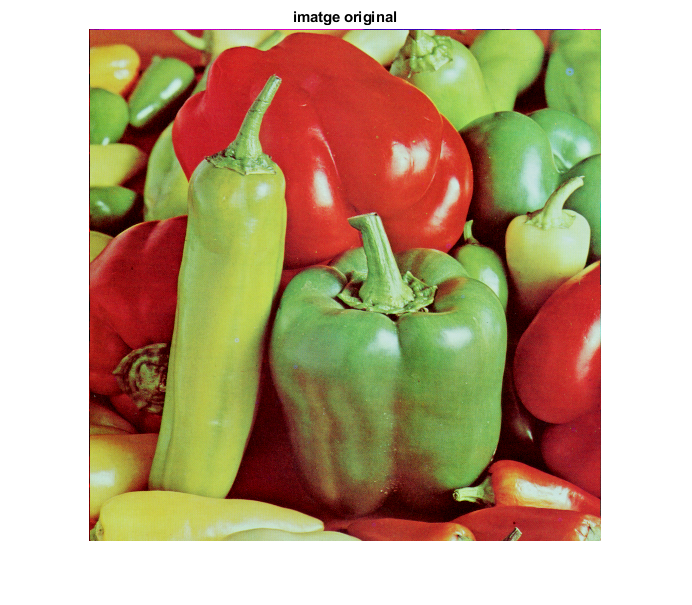

figure,imshow(im),title('imatge original')

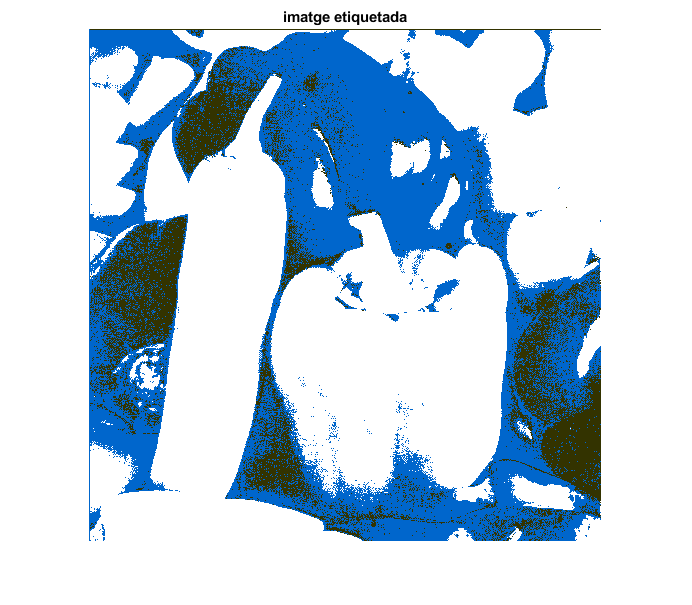


% la segmentarem per color. Treballarem en l’espai Hue-Sat
hsv=rgb2hsv(im);
hs=hsv(:,:,1:2);
vect=reshape(hs,MAXFILA*MAXCOL,2); % feature vector. 2 features per píxel
Nclusters=3; %vermell, verd, i negre
% Usarem la funció kmeans amb distancia citiblock
[cluster_idx, cluster_center] = kmeans(vect,Nclusters,'distance','cityblock');

% obtenim la imatge etiquetada pel número cluster
eti=reshape(cluster_idx,MAXFILA,MAXCOL);
figure,imshow(eti,[]),colormap(colorcube), title('imatge etiquetada')

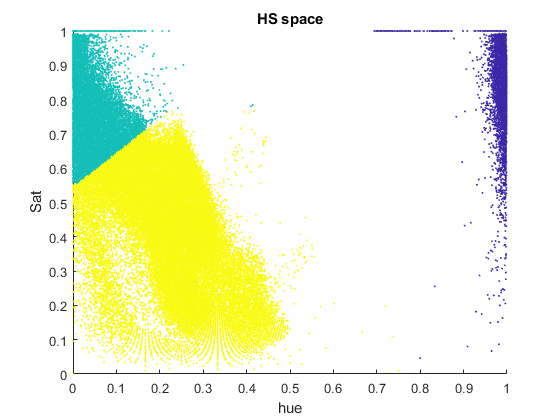

Unrecognized function or variable 'pas'.


% Representem els píxels en l’espai hue-sat
figure,scatter(vect(:,1),vect(:,2),1,cluster_idx);
xlabel('hue');ylabel('Sat')
title('HS space')